# Supply Chain Network Simulator

Designing the Supply Chain Network

clear all
close all
clc

rng(7)

caseNum = 2;

if caseNum == 1
    numOfChains = 2;            % Number of parallel chains
    numOfInventories = 3;       % Number of inventories in each chain
    matFile = 'Results/Case1/gridSearchCompleteDesignResults.mat';
elseif caseNum == 2
    numOfChains = 3;            % Number of parallel chains
    numOfInventories = 4;       % Number of inventories in each chain
    matFile = 'Results/Case2/gridSearchCompleteDesignResults.mat';
elseif caseNum == 3
    numOfChains = 4;            % Number of parallel chains
    numOfInventories = 5;       % Number of inventories in each chain
    matFile = 'Results/Case3/gridSearchCompleteDesignResults.mat';
end

% Create Network
netId = 1;               % Supply chain network ID
net = Network(netId, numOfChains, numOfInventories);

Started creating the supply chain network.
Started creating chain 1
Finished creating a chain...
Started creating chain 2
Finished creating a chain...
Started creating chain 3
Finished creating a chain...
Started creating chain 4
Finished creating a chain...
Finished creating the supply chain network.


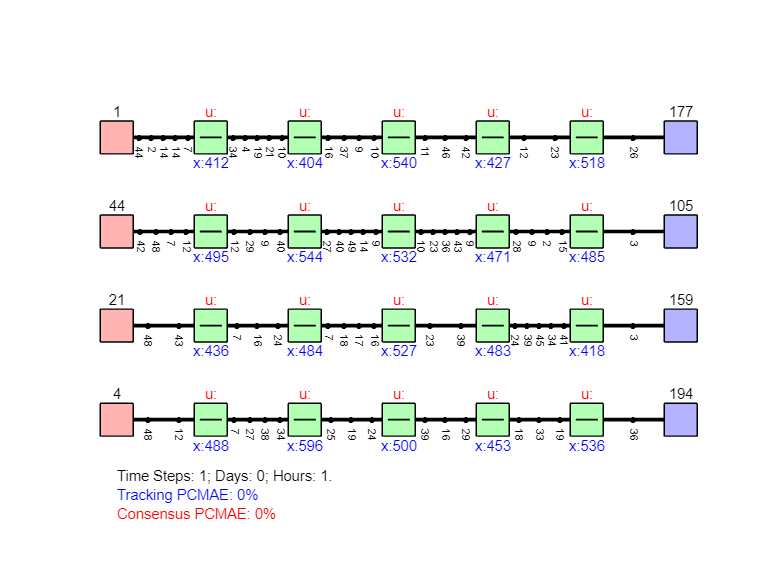


% SCN setup and the initial condition
figNum = 1;
figure(figNum);
hold on; axis equal; axis off;
net.draw(1);


tMax = 24*30 % 4 weeks

tMax = 720

saveMode = 3; % 1 FigSave, 2 vidSave, 3 display


% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)
% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks

d1 = 0;
d2 = -1; %-10
d3 = 0;
d4 = 0;
d5 = 1;
d6 = 0;
[pVal, deltaCostCoef, gammaCostCoef, comCostLimit] = net.findBestParameters(matFile,d1,d2,d3,d4,d5,d6) 

Error in c:
    0.2679   14.3550    0.0283       Inf    0.0207    0.0258

Best parameter combination found:
Minimum objective value: -0.89251
pVal: 0.031623
deltaCostCoef: 1000
gammaCostCoef: 100
comCostLimit: 0.01
LNorm: 1.6516
KNorm: 0.062228
gammaTilde: 247.3291
KLinks: 287
JCon: 30.0017
JTra: 52.1328


pVal = 0.0316

deltaCostCoef = 1000

gammaCostCoef = 100

comCostLimit = 0.0100


% d = [3.1623  0.0010  1.0000  0.1000];
% d = [0.0316    1000    100    0.01];
% d = [0.06    1000    100    0.01];
% pVal = d(1)
% deltaCostCoef = d(2)
% gammaCostCoef = d(3) %100
% comCostLimit = d(4)

save(['tempNet',num2str(caseNum)])
perfData.cumVals = [];
perfData.conHist = [];
perfData.traHist = [];
perfData.caseName{1} = 'CaseNames';
save('caseNum.mat','caseNum','perfData')

Steady state control: K = 0, L = 0

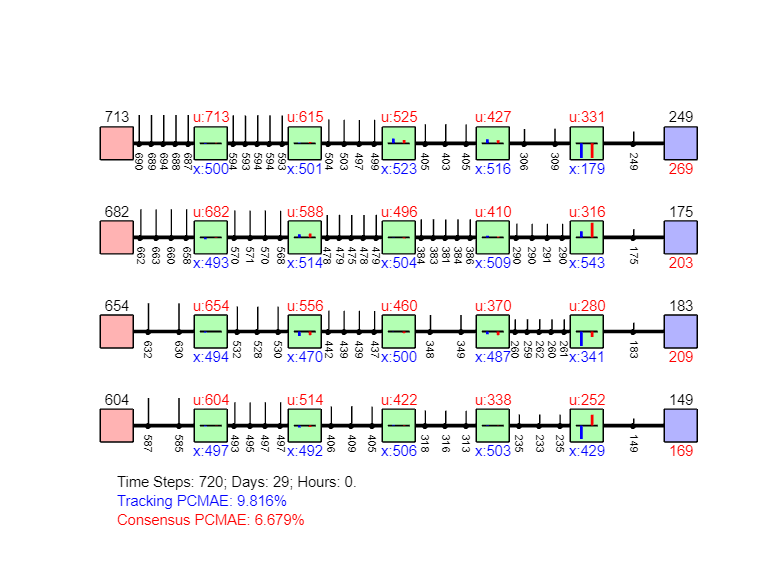

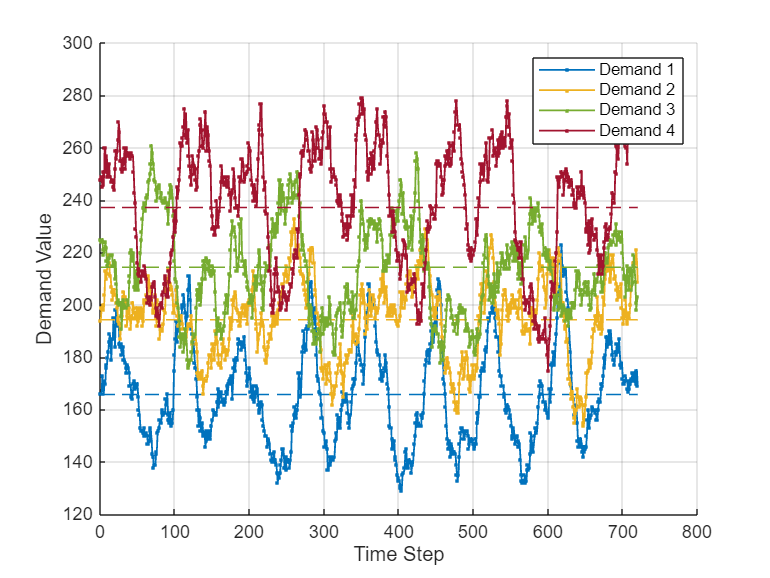

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'Steady';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    net.chains{i}.LLocal = 0*net.chains{i}.LLocal;
end
net.chains{1}.LLocal;
net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
% figNum = figNum + 1;
% figure(figNum); 
% hold on; axis equal; axis off;
% net.plotConnections(net.adjMat);

% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);

    % % Performance plot
    figNum = figNum + 1;
    figure(figNum);
    hold on; grid on;
    net.plotDemandProfiles();
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'SSC';
save('caseNum.mat','caseNum','perfData')

Strict local control: K = 0

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'NullGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])

rng(7)

% Some arbitrarily designed local and global controllers:
for i = 1:numOfChains
    pVal = NaN;
    net.chains{i}.localControlDesign(pVal,deltaCostCoef);
end
net.chains{1}.LLocal

ans =    -0.2139   -0.0743   -0.0505   -0.0368   -0.0271   -0.2376   -0.2858   -0.0825   -0.0931   -0.1068   -0.1250   -0.0561   -0.0624   -0.0696   -0.0409   -0.0453   -0.0502   -0.0301   -0.0333   -0.0369
    0.2270   -0.0658   -0.0405   -0.0290   -0.0214    0.2525    0.1207   -0.0731   -0.0842   -0.1003   -0.1222   -0.0450   -0.0503   -0.0567   -0.0323   -0.0358   -0.0397   -0.0238   -0.0263   -0.0292
    0.0070    0.2784   -0.0842   -0.0510   -0.0372    0.0078    0.0057    0.3096    0.1548    0.0792    0.0404   -0.0935   -0.1087   -0.1310   -0.0566   -0.0630   -0.0704   -0.0413   -0.0456   -0.0505
    0.0007    0.0127    0.2639   -0.1079   -0.0742    0.0007    0.0006    0.0142    0.0109    0.0073    0.0043    0.2936    0.1393    0.0653   -0.1199   -0.1358   -0.1569   -0.0825   -0.0911   -0.1009
   -0.0002    0.0002    0.0057    0.2287   -0.1750   -0.0002   -0.0001    0.0002    0.0002    0.0001   -0.0000    0.0063    0.0044    0.0024    0.2544    0.1069    0.0427   -0.1944   -0.2152

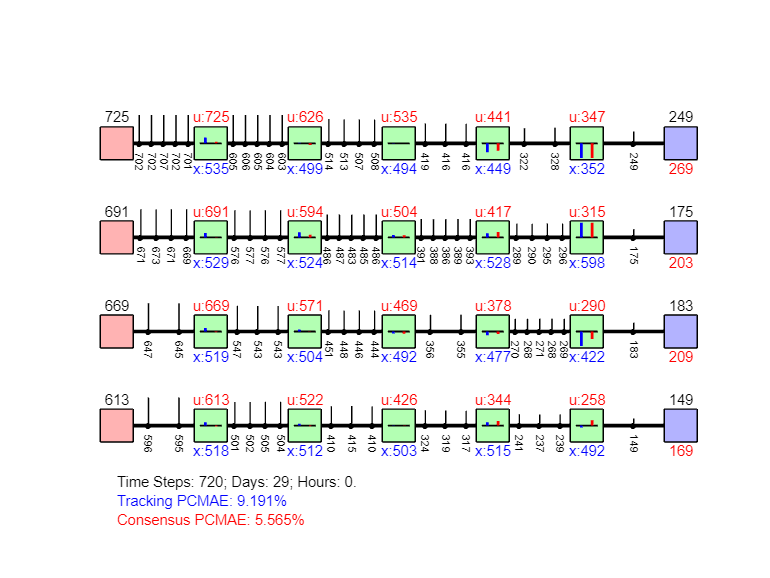

net.KGlobal = 0*net.KGlobal;
net.setAdjointMatrixAndNeighborsAndControllers();


% Communication topology of the arbitrarily global controllers
% figNum = figNum + 1;
% figure(figNum);
% hold on; axis equal; axis off;
% net.plotConnections(net.adjMat);

% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end

    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);

    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'SLC';
save('caseNum.mat','caseNum','perfData')

Distributed Control with Hard Graph 

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 0;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
% d1 = 0;
% d2 = -1; %-10
% d3 = 1;
% d4 = 1;
% [pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 1.6516

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 247.3291

KNormVal = 3.0856e-05

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.3401   -0.2832   -0.2602   -0.2243   -0.1743   -0.3779   -0.4139   -0.3147   -0.3374   -0.3524   -0.3689   -0.2891   -0.3122   -0.3287   -0.2492   -0.2729   -0.2930   -0.1937   -0.2163   -0.2389
    0.1502   -0.2037   -0.1794   -0.1538   -0.1201    0.1669    0.0524   -0.2264   -0.2444   -0.2627   -0.2821   -0.1994   -0.2151   -0.2284   -0.1709   -0.1867   -0.2010   -0.1335   -0.1489   -0.1641
   -0.0315    0.1879   -0.1892   -0.1475   -0.1175   -0.0350   -0.0287    0.2088    0.0653   -0.0034   -0.0338   -0.2102   -0.2279   -0.2532   -0.1638   -0.1759   -0.1890   -0.1305   -0.1407   -0.1521
   -0.0262   -0.0446    0.1847   -0.1939   -0.1512   -0.0291   -0.0234   -0.0496   -0.0489   -0.0495   -0.0473    0.2053    0.0607   -0.0084   -0.2154   -0.2328   -0.2578   -0.1681   -0.1776   -0.1903
   -0.0138   -0.0284   -0.0304    0.1799   -0.2325   -0.0154   -0.0122   -0.0315   -0.0287   -0.0274   -0.0252   -0.0337   -0.0310   -0.0313    0.1999    0.0635    0.0033   -0.2584   -0.2729

net.KGlobal

ans = 1.0e-04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0248   -0.0053   -0.0015   -0.0018         0   -0.0024   -0.0117    0.0008         0         0         0   -0.0030         0         0         0         0         0         0         0         0
   -0.0018    0.0248   -0.0053   -0.0015         0         0   -0.0024   -0.0117    0.0008         0         0         0   -0.0030         0         0         0         0         0         0         0
         0   -0.0019    0.0247   -0.0047   -0.0016         0         0   -0.0023   -0.0122    0.0011         0         0         0   -0.0031         0         0         0         0         0         0
         0         0   -0.0019    0.0246   -0.0049         0         0         0   -0.0024   -0.0125         0         0         0         0   -0.0030         0         0         

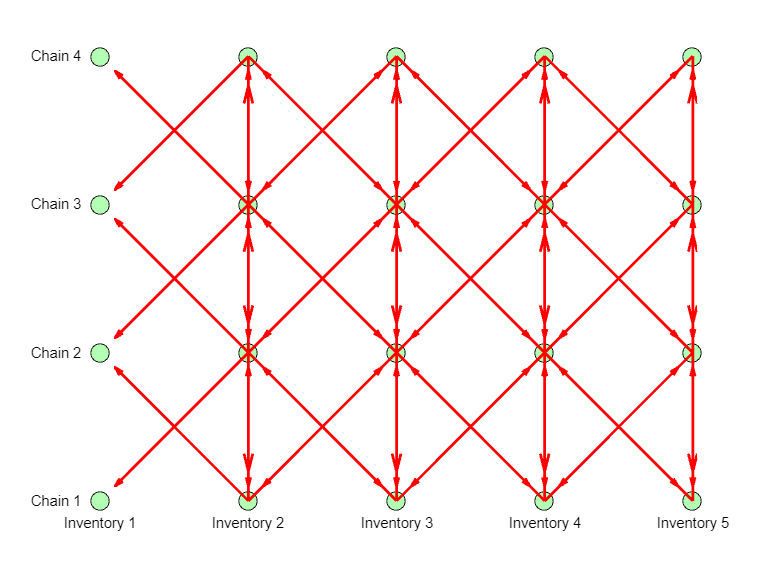


% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

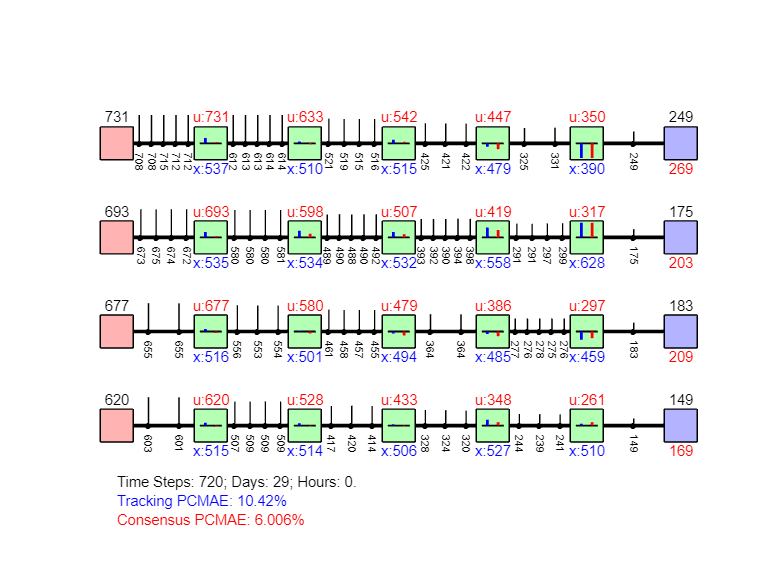


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'DHC';
save('caseNum.mat','caseNum','perfData')

Distributed Control with Soft Graph

clear all
close all
clc

load('caseNum.mat','caseNum','perfData')
tagVal = 'SoftGraph';
folderName = ['Results/Case',num2str(caseNum),'/',tagVal];
load(['tempNet',num2str(caseNum),'.mat'])
rng(7)

isSoft = 1;

% Grid Search Functions (Execute this seperately as it takes time)
% search input parameters: pVal, deltaCostCoef, gammaCostCoef, comCostLimit
% search output metrics: LNorm, KNorm, GammaTilde, KLinks
% net.gridSearchCompleteDesign(folderName)

% Selecting best parameters that optimize the objective J:
% J = d1 * LNormVal + d2 * KNormVal + d3 * gammaTildeVal + d4 * NumOfLinks
% d1 = 0;
% d2 = -1; %-10
% d3 = 1;
% d4 = 1;
% [pVal, deltaCostCoef, gammaCostCoef, comCostLimit, KLinks] = net.findBestParameters(matFile,d1,d2,d3,d4) 

%% Applying the found best parameters to design the local and global controllers
% Local controller design
totalStatusLocal = 1;
totalLNorm = 0;
for i = 1:1:net.numOfChains
    [statusLocal, ~, ~, LNormVal, ~, ~] = net.chains{i}.localControlDesign(pVal, deltaCostCoef);
    if ~statusLocal
        totalStatusLocal = 0;
        break;
    else
        totalLNorm = totalLNorm + LNormVal;
    end
end
totalStatusLocal

totalStatusLocal = 1

totalLNorm = totalLNorm / net.numOfChains

totalLNorm = 1.6516

% Global controller design
if totalStatusLocal
    [statusGlobal, gammaTildeVal, ~, ~, KNormVal] = net.globalControlDesign(gammaCostCoef,comCostLimit,isSoft)
end

statusGlobal = logical
   1


gammaTildeVal = 247.3291

KNormVal = 0.0622

net.setAdjointMatrixAndNeighborsAndControllers(); % Load Graph, neighbors and controllers from KVal

% Optimizally designed local and global controllers:
net.chains{1}.LLocal

ans =    -0.3401   -0.2832   -0.2602   -0.2243   -0.1743   -0.3779   -0.4139   -0.3147   -0.3374   -0.3524   -0.3689   -0.2891   -0.3122   -0.3287   -0.2492   -0.2729   -0.2930   -0.1937   -0.2163   -0.2389
    0.1502   -0.2037   -0.1794   -0.1538   -0.1201    0.1669    0.0524   -0.2264   -0.2444   -0.2627   -0.2821   -0.1994   -0.2151   -0.2284   -0.1709   -0.1867   -0.2010   -0.1335   -0.1489   -0.1641
   -0.0315    0.1879   -0.1892   -0.1475   -0.1175   -0.0350   -0.0287    0.2088    0.0653   -0.0034   -0.0338   -0.2102   -0.2279   -0.2532   -0.1638   -0.1759   -0.1890   -0.1305   -0.1407   -0.1521
   -0.0262   -0.0446    0.1847   -0.1939   -0.1512   -0.0291   -0.0234   -0.0496   -0.0489   -0.0495   -0.0473    0.2053    0.0607   -0.0084   -0.2154   -0.2328   -0.2578   -0.1681   -0.1776   -0.1903
   -0.0138   -0.0284   -0.0304    0.1799   -0.2325   -0.0154   -0.0122   -0.0315   -0.0287   -0.0274   -0.0252   -0.0337   -0.0310   -0.0313    0.1999    0.0635    0.0033   -0.2584   -0.2729

net.KGlobal

ans =    -0.0420   -0.0007         0         0    0.0155         0         0         0         0    0.0049   -0.0052         0         0         0    0.0101         0         0         0    0.0001    0.0174
    0.0002   -0.0018         0         0    0.0003    0.0001    0.0001         0         0    0.0004         0         0         0         0    0.0002         0    0.0003         0         0    0.0001
    0.0002    0.0001   -0.0017    0.0001         0    0.0001         0         0         0    0.0001    0.0001         0         0         0    0.0001    0.0001         0    0.0004         0    0.0002
    0.0003         0         0   -0.0017    0.0002    0.0002         0         0    0.0002         0    0.0002         0         0         0         0    0.0003         0         0    0.0003         0
    0.0004         0         0         0   -0.0013    0.0001         0         0         0         0    0.0001    0.0000         0         0         0    0.0001         0         0         0

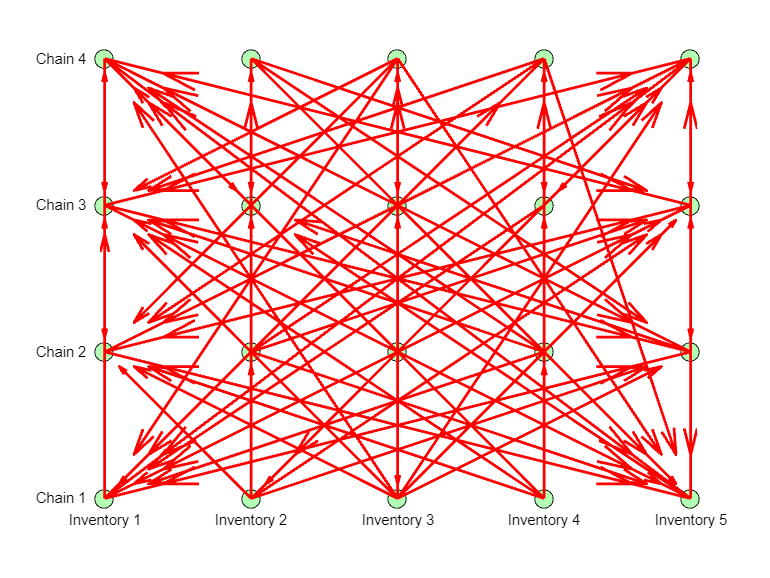


% Communication topology of the optimized global controllers
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.plotConnections(net.adjMat);

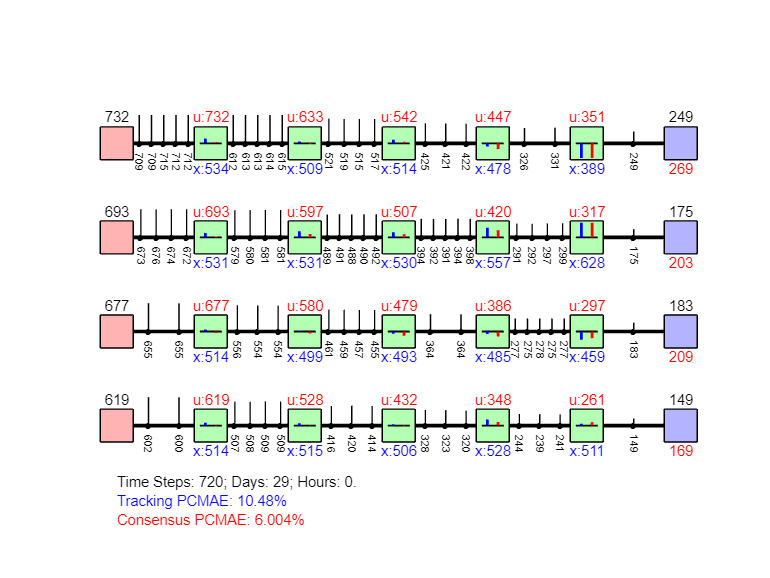


% Simulating the SCN
if saveMode == 1
    % % Run the following save initial and final plots
    net.saveInitialFinalStates(folderName,tMax)
elseif saveMode == 2
    % % Run the following to generate and save videos
    net.runSimulationAndSaveVideos(folderName,tMax)
else
    % Simulation loop
    for t = 1:1:tMax
        net.update();  % Update the entire network
    end
    
    % % Final State
    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;
    net.draw(tMax);
    
    % % Performance plot
    figNum = figNum + 1;
    f = figure(figNum);
    hold on; grid on;
    net.plotNetworkPerformance();
    close(f);
end


perfData.cumVals = [perfData.cumVals; net.cumMeanAbsTraError, net.cumMeanAbsConError];
perfData.conHist = [perfData.conHist; net.consensusErrorHistory];
perfData.traHist = [perfData.traHist; net.trackingErrorHistory];
perfData.caseName{end + 1} = 'DSC';
save('caseNum.mat','caseNum','perfData')

% perfData.cumVals
% What are the inventory capacities that will not limit controllers?
% How to improve tracking error performance without compromizing consensus
% error performance? - Change the local controller design approach....
% Local controllers being overly strong might be causing the osillatory
% behavior, - high control inputs causing overshoots...
% Is there an additional condition on KGlobal for conesensus_tracking
% (e.g., K*1 = 0?, read consensus notes/discussion)

Summary Plots (for the paper)

% A = [40.4448	26.9191; 34.4617	22.8563]
perfData.cumVals

ans =    49.0790   33.3950
   45.9553   27.8226
   52.1040   30.0280
   52.3810   30.0206


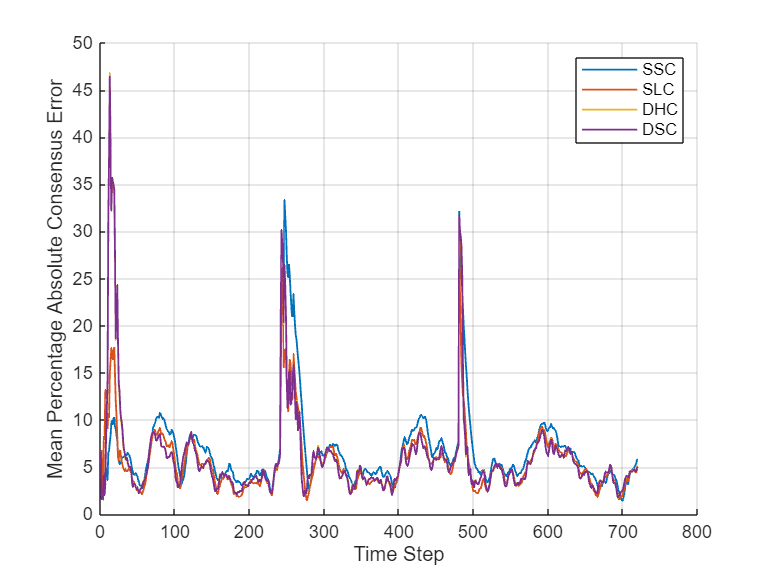


close all
clc

conHist = perfData.conHist;
traHist = perfData.traHist;
caseNames = perfData.caseName;
numCases = size(conHist,1);

L = size(conHist,2);

figNum = figNum + 1;
figure(figNum);
hold on; grid on;
for k = 1:numCases
    plot(1:L, conHist(k,:), '-', 'LineWidth', 1, 'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t));
    xlabel('Time Step');
    ylabel('Mean Percentage Absolute Consensus Error');
    legend('Location', 'northeast');   
end

percentageImprovement = sum(conHist(end-1,:)>=conHist(end,:))*100/L

percentageImprovement = 58.4722

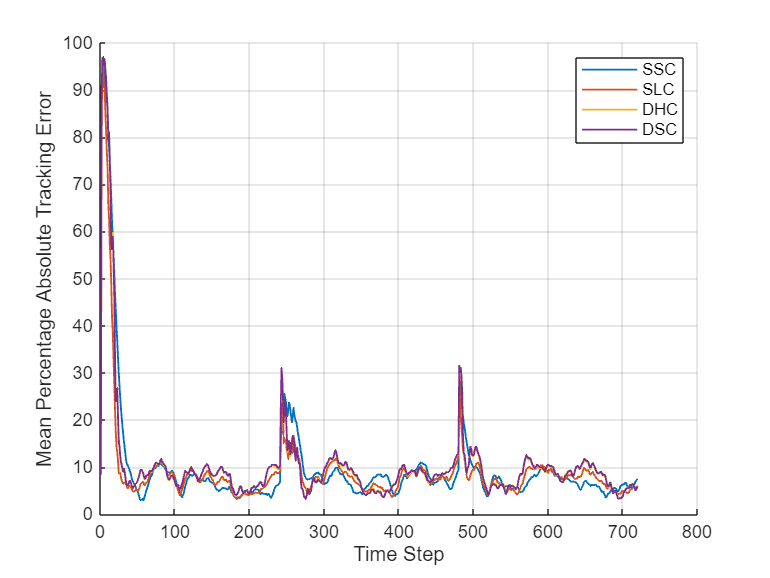


figNum = figNum + 1;
figure(figNum);
hold on; grid on;
for k = 1:numCases
    plot(1:L, traHist(k,:), '-', 'LineWidth', 1, 'DisplayName', caseNames{k+1});
    % title(sprintf('Performance Metrics at Time Step %d', t));
    xlabel('Time Step');
    ylabel('Mean Percentage Absolute Tracking Error');
    legend('Location', 'northeast');   
end

percentageImprovement = sum(traHist(end-1,:)>=traHist(end,:))*100/L

percentageImprovement = 38.4722



% net.printDefaultProperties()